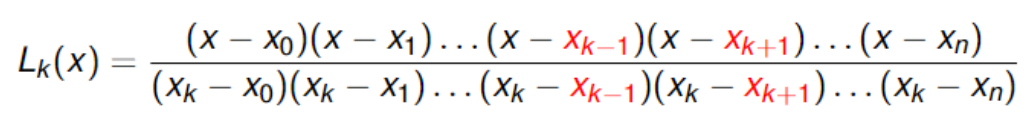

x = [0 0.8 2];
y = [1 0.4 0.2];

a = lagrange(x,y)

a =    0.291666666666667  -0.983333333333333   1.000000000000000


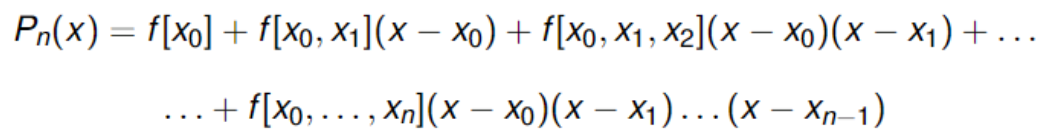

x = [0 0.8 2]';
y = [1 0.4 0.2]';

b = polynewton(x,y)

b =    0.291666666666667  -0.983333333333333   1.000000000000000


Trabajando con polinomios ya hechos

p = [2 0 -6 5] %Coeficientes del polinomio

p =      2     0    -6     5



value01 = polyval(p,2) %Evaluar el 2 en el polinomio con los coeficientes de p

value01 =      9



values01 = polyval(p,[3 5]) %Evaluar el 3 y 5 en el polinomio con los coeficientes de p

values01 =     41   225


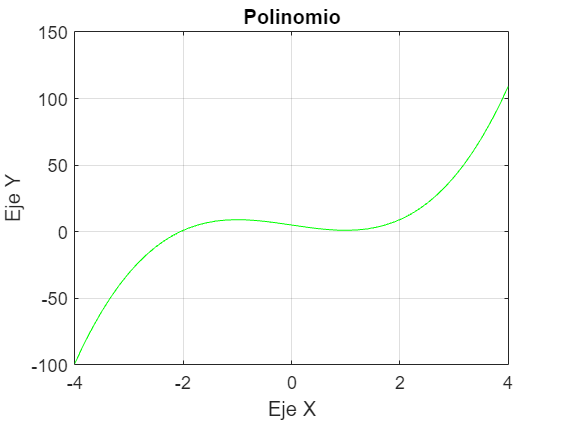


%Graficar el polinomio
xx = linspace(-4,4,50); %intervalo de x con el número de puntos que se unen
yy = polyval(p,xx); %Valores de y son el polinomio de coeficientes p evaluados en los valores xx
plot(xx,yy,'green') 
title('Polinomio')
xlabel('Eje X')
ylabel('Eje Y')
grid on

Crear polinomios desde raices

q = poly([3 7]) %Crea un polinomio que tendra de raices 3 y 7

q =      1   -10    21


qi = poly([3 3 3 3 4 4 6]) %3 multiplicidad de 4, 4 multiplicidad de 2, 6 multiplicidad simple

qi =            1         -26         286       -1728        6201      -13230       15552       -7776


Crear polinomios desde puntos

x=[0 3 4 7]'

x =      0
     3
     4
     7


y=[5 2 6 9]'

y =      5
     2
     6
     9



%Primer metodo matricial
M = [x.^3 x.^2 x ones(4,1)] % Matriz de Vandermonde

M =      0     0     0     1
    27     9     3     1
    64    16     4     1
   343    49     7     1


M = vander(x)

M =      0     0     0     1
    27     9     3     1
    64    16     4     1
   343    49     7     1


p = M\y %inv(M)*y

p =   -0.285714285714286
   3.249999999999998
  -8.178571428571423
   5.000000000000000



%Método automático
p=polyfit(x,y,length(x)-1) %Crea el polinomio que encaja en x y, con el grado de #puntos-1

p =   -0.285714285714286   3.250000000000001  -8.178571428571427   4.999999999999996



%Graficarx
x=[2 2.75 4]';
f=@(x) (1./x)

f = function_handle with value:
    @(x)(1./x)


y=f(x);
p2=polyfit(x,y,2)

p2 =    0.045454545454545  -0.397727272727271   1.113636363636361


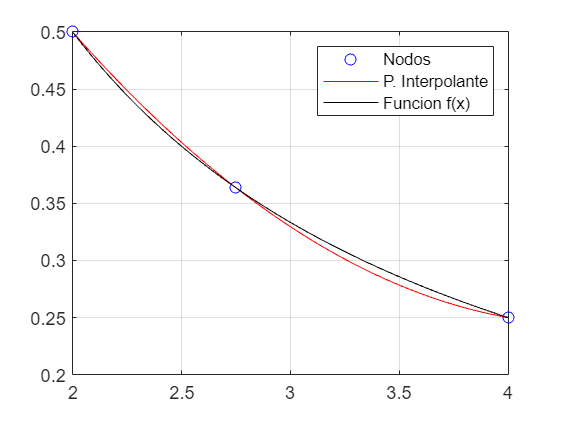

xx=linspace(2,4,50);
yy1=polyval(p2,xx);
yy2=f(xx);
plot(x,y,'ob',xx,yy1,'r',xx,yy2,'k')
grid on
legend('Nodos','P. Interpolante','Funcion f(x)')



x=[0 2 6 7 12 15]

x =      0     2     6     7    12    15


y=[0 4 4 6 7 1]

y =      0     4     4     6     7     1


p=polyfit(x,y,5)

p =    0.001344118844119  -0.050854700854703   0.656555759055791  -3.371452991453185   6.502014652015113  -0.000000000000215


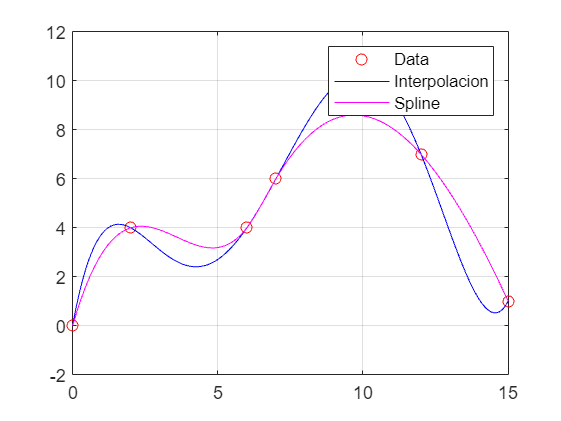

xx=[0:0.01:15];
yy=polyval(p,xx);
plot(x,y,'or',xx,yy,'b')
grid on

%Calculo de 100 puntos de la grafica de S(x)
xx=linspace(0,15,100);
yy=spline(x,y,xx);
%Dibujo de la funcion interpoladora S(x) sobre el conjunto de datos (x,y)
hold on
plot(xx,yy,'m')
legend('Data','Interpolacion','Spline')

Spline Cúbico Natural

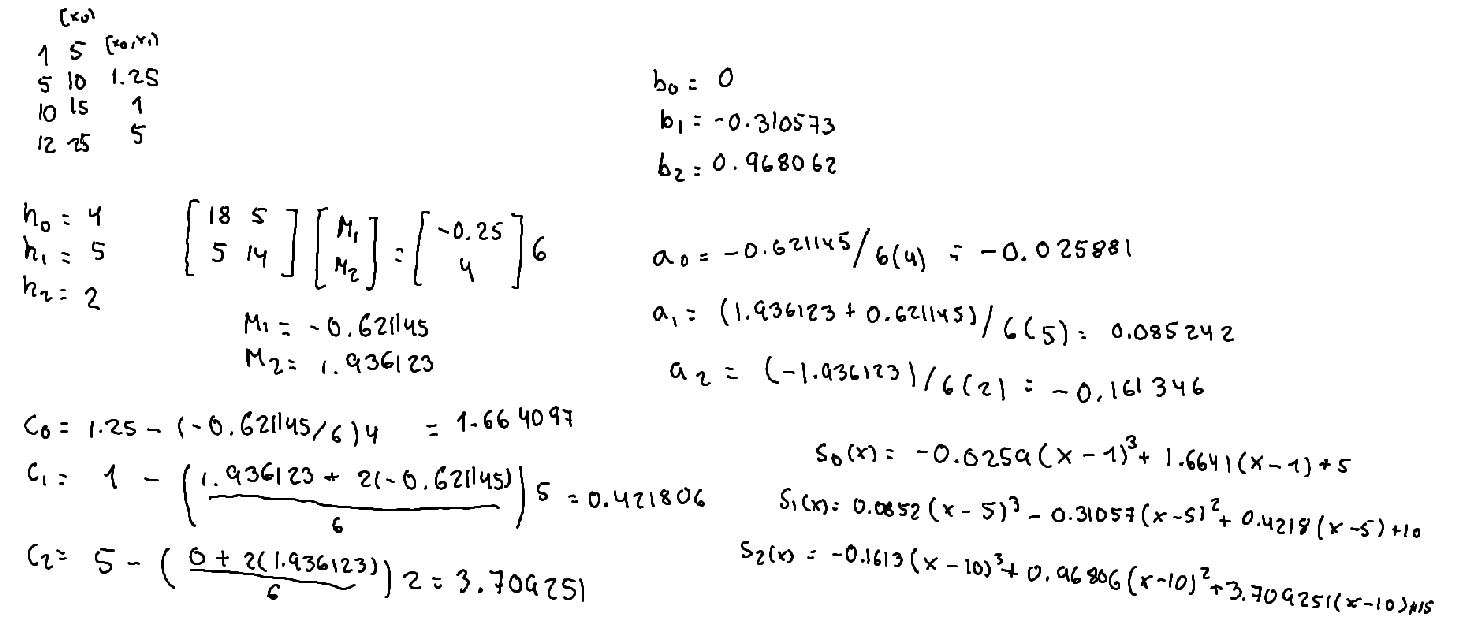

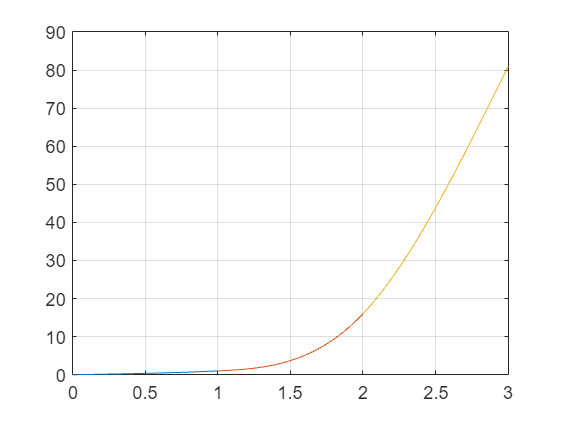

S =    0.400000000000000                   0   0.600000000000000                   0
  12.000000000000000   1.199999999999999   1.799999999999999   1.000000000000000
 -12.400000000000000  37.200000000000003  40.200000000000003  16.000000000000000


clf
x=[0 1 2 3];
y=x.^4;
S=splinenatural(x,y)


coef = S(3, :)

coef =  -12.400000000000000  37.200000000000003  40.200000000000003  16.000000000000000


coef(1)*(2.5-3)^3 + coef(2)*(2.5-3)^2 + coef(3)*(2.5-3) + coef(4)

ans =    6.750000000000000



p = spline(x,y,2.5) %Calcula el spline y lo evalúa en el valor dado

p =   40.000000000000007


Ajuste lineal

%Método automático
x=[1 3 10 16]'

x =      1
     3
    10
    16


y=[4 7 12 8]'

y =      4
     7
    12
     8


g1=polyfit(x,y,1) %lineal xq es de grado 1

g1 =    0.287234042553191   5.595744680851065


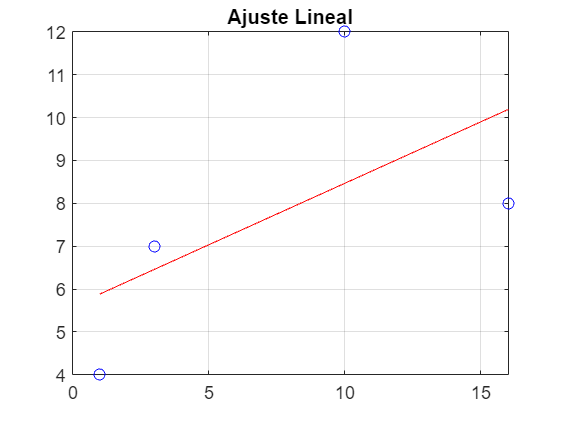

xx=linspace(1,16,50);
yy=polyval(g1,xx);
plot(x,y,'ob',xx,yy,'r')
grid on
title('Ajuste Lineal')



%Método matrices
M=[x ones(4,1)]

M =      1     1
     3     1
    10     1
    16     1


u=inv(M'*M)*M'*y

u =    0.287234042553191
   5.595744680851063


u = M\y

u =    0.287234042553191
   5.595744680851065


Bondad de Ajuste lineal

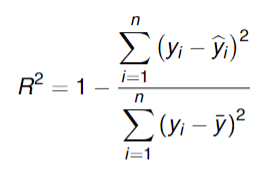                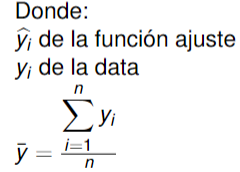

x = [0 3 4 7 9]'

x =      0
     3
     4
     7
     9


y = [0 30 60 90 120]'

y =      0
    30
    60
    90
   120


p1 = polyfit(x,y,1)

p1 =   13.414634146341465  -1.707317073170735


yc = polyval(p1,x)

yc = 1.0e+02 *

  -0.017073170731707
   0.385365853658537
   0.519512195121951
   0.921951219512195
   1.190243902439025


R2 = 1 - sum((y - yc).^2)/sum((y - mean(y)).^2) %Sum representa las sumatorias

R2 =    0.983739837398374


Ajuste cuadrático

x=[1 3 10 16]'

x =      1
     3
    10
    16


y=[4 7 12 8]'

y =      4
     7
    12
     8



M=[x.^2 x ones(4,1)]

M =      1     1     1
     9     3     1
   100    10     1
   256    16     1


u=inv(M'*M)*M'*y

u =   -0.102944950596689
   2.024156294110089
   1.988290773771351


u = M\y

u =   -0.102944950596689
   2.024156294110099
   1.988290773771334



u=polyfit(x,y,2)

u =   -0.102944950596689   2.024156294110099   1.988290773771334


Linealización

x1=[1 3 10 16]'

x1 =      1
     3
    10
    16


y1=[4 7 12 8]'

y1 =      4
     7
    12
     8



X=x1;
Y=log(y1)

Y =    1.386294361119891
   1.945910149055313
   2.484906649788000
   2.079441541679836



g1=polyfit(X,Y,1)

g1 =    0.043404331281705   1.648605690797973


A=g1(1)

A =    0.043404331281705


C=exp(g1(2))

C =    5.199724746380385


syms x
g=inline(subs(C*exp(A*x)),'x')

g =

     Inline function:
     g(x) = exp(x.*4.340433128170501e-2).*5.199724746380385



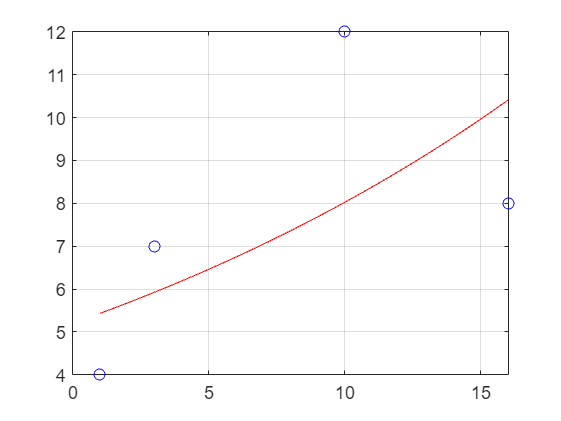

xx=linspace(1,16,50);
yy=g(xx);
plot(xx,yy,'r',x1,y1,'ob')
grid on

Pendiente de regresión lineal

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long
b1 = x\y %Esto hace la regresión lineal de mínimos cuadrados, b1

b1 =      1.372716735564871e-04



yc1 = b1*x; %La regresión la multiplica por cada valor y saca uno nuebo
scatter(x,y,'r')
hold on
plot(x,yc1,'b')
xlabel('Poblacion del estado')
ylabel('Accidentes de trafico mortales por estado')
title('Relacion de regresion lineal entre accidentes y poblacion')
grid on

%Lo siguiente es para no dejar la funcion como bx, sino como b1 + bx
X = [ones(length(x),1) x];
format long
b = X\y

b = 1.0e+02 *

   1.427120171726538
   0.000001256394274


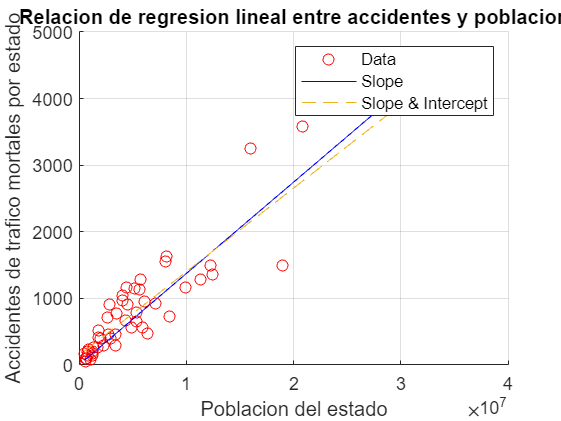

yc2 = X*b;
plot(x,yc2,'--')

legend('Data','Slope','Slope & Intercept');

Rsq1 = 1 - sum((y - yc1).^2)/sum((y - mean(y)).^2)

Rsq1 =    0.822235650485566


Rsq2 = 1 - sum((y - yc2).^2)/sum((y - mean(y)).^2)

Rsq2 =    0.838210531103428


Funciones

function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
    S(i,1)=(g(i+1)-g(i))/(6*H(i));
    S(i,2)=g(i)/2;
    S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
    S(i,4)=Y(i);
    xx=linspace(X(i),X(i+1),100);
    yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
end
end



function M=tabladif(x,y)
n=length(x);
M=zeros(n);
M(1:n,1)=y;
for k=1:n-1
    dx=x(k+1:n)-x(1:n-k);
    dy=diff(y)./dx;
    M(1:n-k,k+1)=dy;
    y=dy;
end
M=[x M];
end



function p=polynewton(x,y)
M=tabladif(x,y);
n=length(x);
b=M(1,2:end);
p=b(1);
for k=2:n
    p =[0 p]+b(k)*poly(x(1:k-1));
end
end



function p=lagrange(x,y)
n=length(x);
p=zeros(1,n);
for k=1:n
    num=poly(x([1:k-1,k+1:n]));
    den=polyval(num,x(k));
    L=num/den;
    p=p+y(k)*L;
end
end